C = [2 3 3; 1 2 3;1 1 2];
V = [1 2 3;2 4 6;3 6 9];
ax=axes ;
hold on
[X,Y] = meshgrid(1:size(C,1),1:size(C,2));
h = imagesc(X(:),Y(:),flipud(C))

h =   Image with properties:

           CData: [3×3 double]
    CDataMapping: 'scaled'

  Show all properties


cmap = [0 1 0;1 1 0;1 0 0];%remember to rename the cmap or colormap for 
%different matrix size.
%notice that the when we create the cmap/colormap variable, the value is
%determined,for the first run. 
%for example: if we use 3x3 matrix and then we want to do the 5x5 matrix,
%the cmap and color map is determined already, this will casue the 5x5
%matrix color look wrong. 
str = sprintfc('%d',V(:))

str = 9×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'2'}
    {'4'}
    {'6'}
    {'3'}
    {'6'}
    {'9'}


text(X(:),Y(:),str)
RowLabels = {'unlikely','possible','very likely'};
ColLabels = {'negligible','moderate','severe'};
set(gca,'xtick',unique(X),...
    'ytick',unique(Y),...
    'yticklabels',RowLabels,...
    'xticklabels',ColLabels)
cb = colorbar(ax,'location','southoutside')

cb =   ColorBar with properties:

    Location: 'southoutside'
      Limits: [1 3]
    FontSize: 9
    Position: [0.1298 0.1524 0.7750 0.0508]
       Units: 'normalized'

  Show all properties


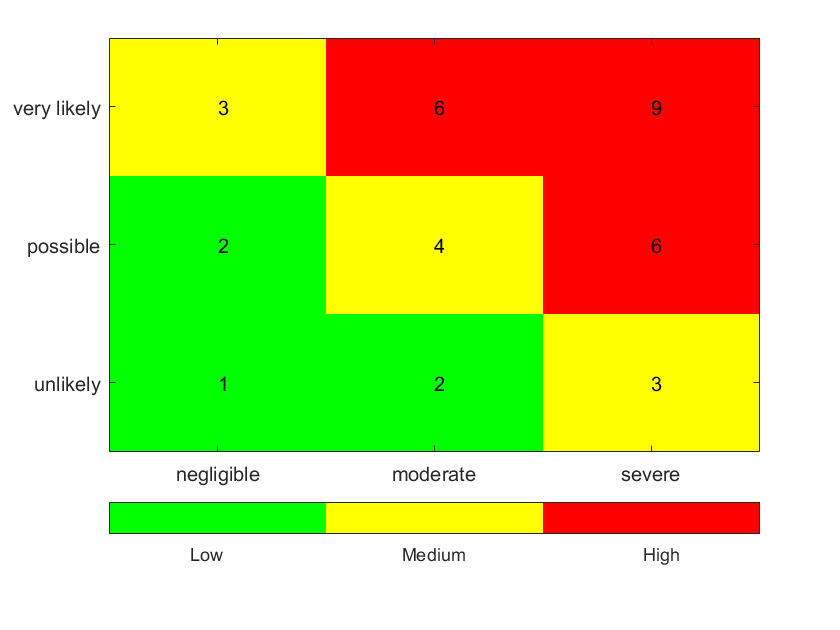

set(cb,'ticks',[1.3 2 2.7],...
    'ticklabels',{'Low','Medium','High'},...
    'ticklength',0)
box on
set(ax,'layer','top')
colormap(cmap)

Please Enter the Risk Probability

Probability_1 = 2

Probability_1 = 2

Please Enter the Risk Severity 

Severity_1 = 1

Severity_1 = 1

The Risk Level of this hazard is:

Risk_level_3_by_3 = Probability_1 * Severity_1;
 if Risk_level_3_by_3 < 3;
     Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
     'Score 1-2： Negligible Risk Level.'];
     disp(Result_3);
 elseif (2 < Risk_level_3_by_3)&& (Risk_level_3_by_3 <6); 
     Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
     'Score 3-4: Medium Level, recommending reduce the level and report to the facility.'];
     disp(Result_3);
 else
     Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
     'Score 6-9: Immediate Action Required: Report to the facility and seek actions.'];
     disp(Result_3);
end

The Risk level of this hazard is 2 .Score 1-2： Negligible Risk Level.



% Result_3 = ['The Risk level of this hazard is ', num2str(Risk_level_3_by_3), ' .',...
%     'Score 1-2： Negligible Risk Level.',...
%     'Score 3-4: Medium Level, recommending reduce the level and report to the facility.',...
%     'Score 6-9: Immediate Action Required: Report to the facility and seek actions.'];
% disp(Result_3);